% Name: James Prime
% Student ID: 215028657
% TA: Miodrag Tasic

% Lab 3: Projectile Motion Simulation
% Lab Goal: To simulate the motion of a projectile launched at an angle with an initial velocity.

% initialize environment
clc; clear;

% Projectile Motion Function Block

function [t, x, y, flightTime, hRange, maxHeight] = projectile_motion(v0, theta, g)
    % confirm floating point inputs
    if ~isfloat(v0) || ~isfloat(theta) || ~isfloat(g)
        error('All inputs must be floating point numbers.');
    end
    
    % Convert angle to radians
    theta_rad = deg2rad(theta);
    
    % Calculate time of flight
    t_flight = (2 * v0 * sin(theta_rad)) / g;
    
    % Time vector
    t = linspace(0, t_flight, 100);
    
    % Calculate x and y positions
    x = v0 * cos(theta_rad) .* t;
    y = (v0 * sin(theta_rad) .* t) - (0.5 * g .* t.^2);

    % Int value output
    flightTime = t_flight;
    hRange = v0*v0*sin(2*theta_rad)/g;
    maxHeight = v0*v0*sin(theta_rad)*sin(theta_rad)/(2*g);
end

% Input Block
v0 = input('Enter the initial velocity v0 (m/s): ');
theta = input('Enter the launch angle theta (degrees): ');
g = input('Enter the gravitational acceleration g (m/s^2): ');

% Get vectors, display output, and plot
[t, x, y, flightTime, hRange, maxHeight] = projectile_motion(v0, theta, g);

% display output
fprintf("You Entered v0 = %.4e, theta = %.4e degrees, and g = %.4e m/s^2.\n", v0, theta, g);

You Entered v0 = 2.5000e+01, theta = 4.0000e+01 degrees, and g = 9.8100e+00 m/s^2.


fprintf("Total Flight Time = %.4e s\n", flightTime);

Total Flight Time = 3.2762e+00 s


fprintf("Horizontal Range = %.4e m\n", hRange);

Horizontal Range = 6.2743e+01 m


fprintf("Maximum Height = %.4e m\n", maxHeight);

Maximum Height = 1.3162e+01 m


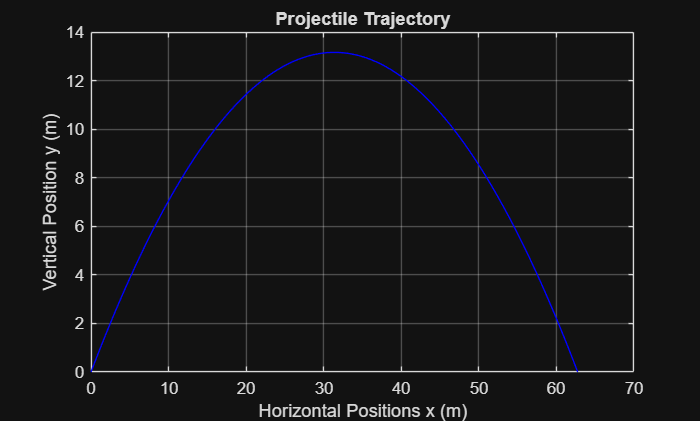


% plot table
plot(x,y,'b-')
grid on;
xlabel("Horizontal Positions x (m)")
ylabel("Vertical Position y (m)")
title("Projectile Trajectory")